## 50 step for Frequency-Shaped LQR (FS-LQR)

step_amplitude = 50;

FS_LQR_sysG = ss(A, B, C, D);
FS_LQR_sysG_pole = pole(FS_LQR_sysG);
disp(FS_LQR_sysG_pole);

   0.0000 + 0.0000i
  -2.0896 +41.2232i
  -2.0896 -41.2232i
  -3.3943 + 0.0000i



% w0 è il modulo del polo complesso

FS_LQR_w0 = abs(FS_LQR_sysG_pole(2));
FS_LQR_q22 =[0.01 1 100];

FS_LQR_thh_bar = 5*pi/180;
FS_LQR_u_bar = 100;


## matrici prime

FS_LQR_actual = 1;

FS_LQR_A_q_prime = [0 1; -FS_LQR_w0^2 0];
FS_LQR_B_q_prime = [0; 1];
FS_LQR_C_q_prime = [sqrt(FS_LQR_q22(FS_LQR_actual))*FS_LQR_w0^2 0];
FS_LQR_D_q_prime = 0;

% definition of necesseray Q matrices
FS_LQR_A_q = FS_LQR_A_q_prime;
FS_LQR_B_q = [zeros(2,1) FS_LQR_B_q_prime zeros(2)];
FS_LQR_C_q = [zeros(1,2); FS_LQR_C_q_prime; zeros(2)];
FS_LQR_D_q = diag([1/FS_LQR_thh_bar FS_LQR_D_q_prime 0 0]);

% definition of necesseray A matrices
FS_LQR_A_q_AA = [A zeros(4,2); FS_LQR_B_q FS_LQR_A_q];
FS_LQR_A_q_BA = [B; zeros(2,1)];
FS_LQR_A_q_CA = [C zeros(1,2)];
FS_LQR_A_q_DA = 0;
FS_LQR_A_q_QA = [FS_LQR_D_q'*FS_LQR_D_q  FS_LQR_D_q'*FS_LQR_C_q ;
                    FS_LQR_C_q'*FS_LQR_D_q  FS_LQR_C_q'*FS_LQR_C_q ];

FS_LQR_A_q_RA = 1/FS_LQR_u_bar^2;
FS_LQR_A_q_K = lqr(FS_LQR_A_q_AA, FS_LQR_A_q_BA, FS_LQR_A_q_QA, FS_LQR_A_q_RA);

FS_LQR_A_q_N = [FS_LQR_A_q_AA FS_LQR_A_q_BA; FS_LQR_A_q_CA FS_LQR_A_q_DA]\[zeros(6,1); 1];
FS_LQR_A_q_Nx = FS_LQR_A_q_N(1:6);
FS_LQR_A_q_Nu = FS_LQR_A_q_N(7);

FS_LQR_I = eye(2);
FS_LQR_zero = zeros(2,4);

% simulate value with step 50 [deg] integral lqr Bryson q11_1



data = sim("lab3_fs_lqr_sim.slx");

t1 = data.ScopeData1.time;
tetha_h1 = data.ScopeData1.signals(1).values;  
tetha_d1 = data.ScopeData1.signals(2).values;
ref_signal1 = data.ScopeData1.signals(3).values;
command_u1 =  data.ScopeData1.signals(4).values;

save("lab3_fs_lqr_1",'t1','tetha_h1','tetha_d1','ref_signal1','command_u1');


FS_LQR_actual = 2;

FS_LQR_A_q_prime = [0 1; -FS_LQR_w0^2 0];
FS_LQR_B_q_prime = [0; 1];
FS_LQR_C_q_prime = [sqrt(FS_LQR_q22(FS_LQR_actual))*FS_LQR_w0^2 0];
FS_LQR_D_q_prime = 0;

% definition of necesseray Q matrices
FS_LQR_A_q = FS_LQR_A_q_prime;
FS_LQR_B_q = [zeros(2,1) FS_LQR_B_q_prime zeros(2)];
FS_LQR_C_q = [zeros(1,2); FS_LQR_C_q_prime; zeros(2)];
FS_LQR_D_q = diag([1/FS_LQR_thh_bar FS_LQR_D_q_prime 0 0]);

% definition of necesseray A matrices
FS_LQR_A_q_AA = [A zeros(4,2); FS_LQR_B_q FS_LQR_A_q];
FS_LQR_A_q_BA = [B; zeros(2,1)];
FS_LQR_A_q_CA = [C zeros(1,2)];
FS_LQR_A_q_DA = 0;
FS_LQR_A_q_QA = [FS_LQR_D_q'*FS_LQR_D_q  FS_LQR_D_q'*FS_LQR_C_q ;
                    FS_LQR_C_q'*FS_LQR_D_q  FS_LQR_C_q'*FS_LQR_C_q ];

FS_LQR_A_q_RA = 1/FS_LQR_u_bar^2;
FS_LQR_A_q_K = lqr(FS_LQR_A_q_AA, FS_LQR_A_q_BA, FS_LQR_A_q_QA, FS_LQR_A_q_RA);

FS_LQR_A_q_N = [FS_LQR_A_q_AA FS_LQR_A_q_BA; FS_LQR_A_q_CA FS_LQR_A_q_DA]\[zeros(6,1); 1];
FS_LQR_A_q_Nx = FS_LQR_A_q_N(1:6);
FS_LQR_A_q_Nu = FS_LQR_A_q_N(7);

FS_LQR_I = eye(2);
FS_LQR_zero = zeros(2,4);

% simulate value with step 50 [deg] integral lqr Bryson q11_1



data = sim("lab3_fs_lqr_sim.slx");

t2 = data.ScopeData1.time;
tetha_h2 = data.ScopeData1.signals(1).values;  
tetha_d2 = data.ScopeData1.signals(2).values;
ref_signal2 = data.ScopeData1.signals(3).values;
command_u2 =  data.ScopeData1.signals(4).values;

save("lab3_fs_lqr_2",'t2','tetha_h2','tetha_d2','ref_signal2','command_u2');


FS_LQR_actual = 3;

FS_LQR_A_q_prime = [0 1; -FS_LQR_w0^2 0];
FS_LQR_B_q_prime = [0; 1];
FS_LQR_C_q_prime = [sqrt(FS_LQR_q22(FS_LQR_actual))*FS_LQR_w0^2 0];
FS_LQR_D_q_prime = 0;

% definition of necesseray Q matrices
FS_LQR_A_q = FS_LQR_A_q_prime;
FS_LQR_B_q = [zeros(2,1) FS_LQR_B_q_prime zeros(2)];
FS_LQR_C_q = [zeros(1,2); FS_LQR_C_q_prime; zeros(2)];
FS_LQR_D_q = diag([1/FS_LQR_thh_bar FS_LQR_D_q_prime 0 0]);

% definition of necesseray A matrices
FS_LQR_A_q_AA = [A zeros(4,2); FS_LQR_B_q FS_LQR_A_q];
FS_LQR_A_q_BA = [B; zeros(2,1)];
FS_LQR_A_q_CA = [C zeros(1,2)];
FS_LQR_A_q_DA = 0;
FS_LQR_A_q_QA = [FS_LQR_D_q'*FS_LQR_D_q  FS_LQR_D_q'*FS_LQR_C_q ;
                    FS_LQR_C_q'*FS_LQR_D_q  FS_LQR_C_q'*FS_LQR_C_q ];

FS_LQR_A_q_RA = 1/FS_LQR_u_bar^2;
FS_LQR_A_q_K = lqr(FS_LQR_A_q_AA, FS_LQR_A_q_BA, FS_LQR_A_q_QA, FS_LQR_A_q_RA);

FS_LQR_A_q_N = [FS_LQR_A_q_AA FS_LQR_A_q_BA; FS_LQR_A_q_CA FS_LQR_A_q_DA]\[zeros(6,1); 1];
FS_LQR_A_q_Nx = FS_LQR_A_q_N(1:6);
FS_LQR_A_q_Nu = FS_LQR_A_q_N(7);

FS_LQR_I = eye(2);
FS_LQR_zero = zeros(2,4);

% simulate value with step 50 [deg] integral lqr Bryson q11_1

data = sim("lab3_fs_lqr_sim.slx");

t3 = data.ScopeData1.time;
tetha_h3 = data.ScopeData1.signals(1).values;  
tetha_d3 = data.ScopeData1.signals(2).values;
ref_signal3 = data.ScopeData1.signals(3).values;
command_u3 =  data.ScopeData1.signals(4).values;

save("lab3_fs_lqr_3",'t3','tetha_h3','tetha_d3','ref_signal3','command_u3');


## Stampa grafico tetha_h

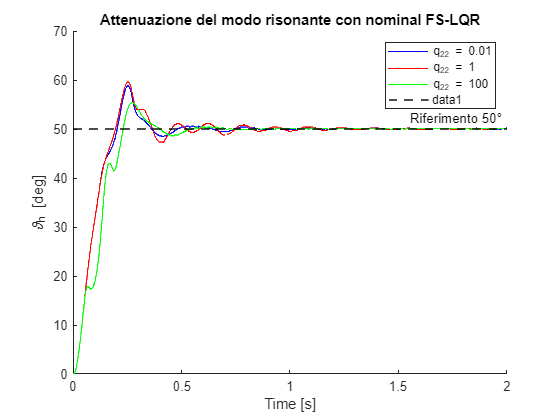


% grafico step 50 deg

load("lab3_fs_lqr_1.mat");
load("lab3_fs_lqr_2.mat");
load("lab3_fs_lqr_3.mat");

figure;
hold on 
plot(t1,tetha_h1,'b');
plot(t2,tetha_h2,'r');
plot(t3,tetha_h3,'g');
axis([0 2 0 70])
xlabel('Time [s]');
ylabel('\vartheta_h [deg]');
legend('q_{22} = 0.01', 'q_{22} = 1', 'q_{22} = 100');
yline(50, 'k--', 'Riferimento 50°', 'LineWidth', 1.5);
title('Attenuazione del modo risonante con nominal FS-LQR');
hold off

## Stampa grafico tetha_d

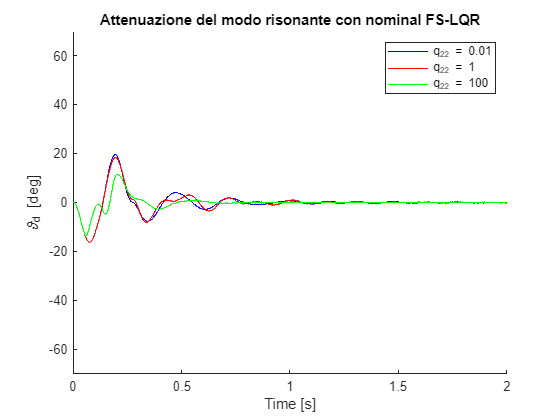


figure;
hold on 
plot(t1,tetha_d1,'b');
plot(t2,tetha_d2,'r');
plot(t3,tetha_d3,'g');
axis([0 2 -70 70])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
legend('q_{22} = 0.01', 'q_{22} = 1', 'q_{22} = 100');
title('Attenuazione del modo risonante con nominal FS-LQR');
hold off

Certamente! L'obiettivo del punto 10 è farti osservare l'effetto "magico" del Frequency-Shaped LQR rispetto a un LQR standard.

Come hai visto teoricamente, il parametro $q_{22}$ agisce come una sorta di "volume" per il filtro centrato sulla frequenza di risonanza $\omega_0$. Più alzi questo valore, più intimi al controllore: *"Non azzardarti a far vibrare il braccio a questa precisa frequenza, a qualunque costo"*.  

Ecco l'esito (la valutazione) che devi documentare osservando i grafici della deflessione del raggio ($\vartheta_d$) per le tre opzioni:

- **Con ****$q_{22} = 0.01$**** (Attenuazione minima / Filtro "pigro"):**Il controllore dà pochissima importanza alle vibrazioni della molla. Ricorda che al punto 9 hai impostato un peso molto severo sull'errore di posizione del mozzo ($\bar{\vartheta}_h = 5^\circ$ invece di $15^\circ$). Questo costringe il motore a scattare in modo rapidissimo verso i 50°. Di conseguenza, il braccio flessibile subisce una "frustata" clamorosa. Nel grafico di $\vartheta_d$ vedrai **oscillazioni molto ampie, evidenti e persistenti** alla frequenza $\omega_0$. Il modo risonante è quasi del tutto libero di sfogarsi.  

- **Con ****$q_{22} = 1$**** (Attenuazione moderata / Il compromesso):**Il peso inizia a farsi sentire. Il controllore bilancia la necessità di arrivare a 50° in fretta con l'esigenza di non spaccare il giunto elastico. Rispetto al caso precedente, vedrai che l'ampiezza massima (il picco) della deflessione $\vartheta_d$ si riduce visibilmente e, soprattutto, **le oscillazioni si smorzano molto più in fretta**. Il profilo di velocità del motore diventa un po' più "intelligente".

- **Con ****$q_{22} = 100$**** (Soppressione aggressiva / Attenuazione massima):**Qui vedi il FS-LQR in tutta la sua potenza. Il controllore penalizza in modo estremo qualsiasi dinamica vicina alla frequenza di risonanza $\omega_0$. Sul grafico di $\vartheta_d$, **il modo risonante risulterà quasi completamente soppresso**. Vedrai una deflessione piccolissima e praticamente priva di *ringing* (quei classici "rimbalzi" su e giù).

**Cosa sta succedendo dietro le quinte?**Per ottenere l'abbattimento totale delle vibrazioni a $q_{22} = 100$, il controllore LQR calcola un segnale di tensione $u$ che, se analizzato in frequenza, possiede una sorta di "buco" (un effetto *notch*) proprio in corrispondenza di $\omega_0$. In pratica, il motore si muove in modo da sottrarre dal suo transitorio esattamente l'energia meccanica che innescherebbe la risonanza del giunto. 

#### Step response parameters


step_50_wind_up_nominal_lqr_1 = stepinfo(tetha_h1, t1, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr_1);

         RiseTime: 0.1388
    TransientTime: 0.3039
     SettlingTime: 0.3039
      SettlingMin: 45.1800
      SettlingMax: 58.8600
        Overshoot: 17.7200
       Undershoot: 0
             Peak: 58.8600
         PeakTime: 0.2500



step_50_wind_up_nominal_lqr_2 = stepinfo(tetha_h2, t2, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr_2);

         RiseTime: 0.1319
    TransientTime: 0.4180
     SettlingTime: 0.4180
      SettlingMin: 45.1800
      SettlingMax: 59.5800
        Overshoot: 19.1600
       Undershoot: 0
             Peak: 59.5800
         PeakTime: 0.2490



step_50_wind_up_nominal_lqr_3 = stepinfo(tetha_h3, t3, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr_3);

         RiseTime: 0.1829
    TransientTime: 0.3219
     SettlingTime: 0.3219
      SettlingMin: 45.1800
      SettlingMax: 55.4400
        Overshoot: 10.8800
       Undershoot: 0
             Peak: 55.4400
         PeakTime: 0.2710



## Final table


q11_values = [0.01 ; 1 ; 100];

settling_times = [
    step_50_wind_up_nominal_lqr_1.SettlingTime;
    step_50_wind_up_nominal_lqr_2.SettlingTime;
    step_50_wind_up_nominal_lqr_3.SettlingTime;
];

overshoots = [
    step_50_wind_up_nominal_lqr_1.Overshoot;
    step_50_wind_up_nominal_lqr_2.Overshoot;
    step_50_wind_up_nominal_lqr_3.Overshoot;
];

Tabella_Risultati_LQR = table(q11_values, settling_times, overshoots, ...
    'VariableNames', {'Peso_q11', 'SettlingTime_sec', 'Overshoot_perc'});

disp('--- Risultati Test LQR con Azione Integrale ---');

--- Risultati Test LQR con Azione Integrale ---


disp(Tabella_Risultati_LQR);

    Peso_q11    SettlingTime_sec    Overshoot_perc
    ________    ________________    ______________

      0.01          0.30391             17.72     
         1          0.41798             19.16     
       100          0.32193             10.88     

